clc,clear;

%% read
path('./Atheros_csi', path);
csi_profile = read_log_file('./ap1_2.log');


n_entry = length(csi_profile);
tmp_rssi1 = zeros(1, n_entry);
packet_rate = zeros(1, n_entry);
csi_magnitude = zeros(1, n_entry);
csi_phase = zeros(1, n_entry);

counter = 0;
%% rssi
for j = 1:n_entry
    tmp_rssi1(j) = csi_profile{j}.rssi3;
    if j == 1
        packet_rate(j) = 1/((csi_profile{j+1}.timestamp - csi_profile{j}.timestamp)*1e-6);
    elseif j == n_entry
        packet_rate(j) = 1/((csi_profile{j}.timestamp - csi_profile{j-1}.timestamp)*1e-6);
    else
        packet_rate(j) = 2/((csi_profile{j+1}.timestamp - csi_profile{j-1}.timestamp)*1e-6);
    end
    if csi_profile{j}.csi_len
        csi_magnitude(j) = abs(csi_profile{j}.csi(1,1,1));
        csi_phase(j) = rad2deg(angle(csi_profile{j}.csi(1,1,1)));
        counter = counter + 1;
    else
        csi_magnitude(j) = -1;
        csi_phase(j) = -1;
    end
end

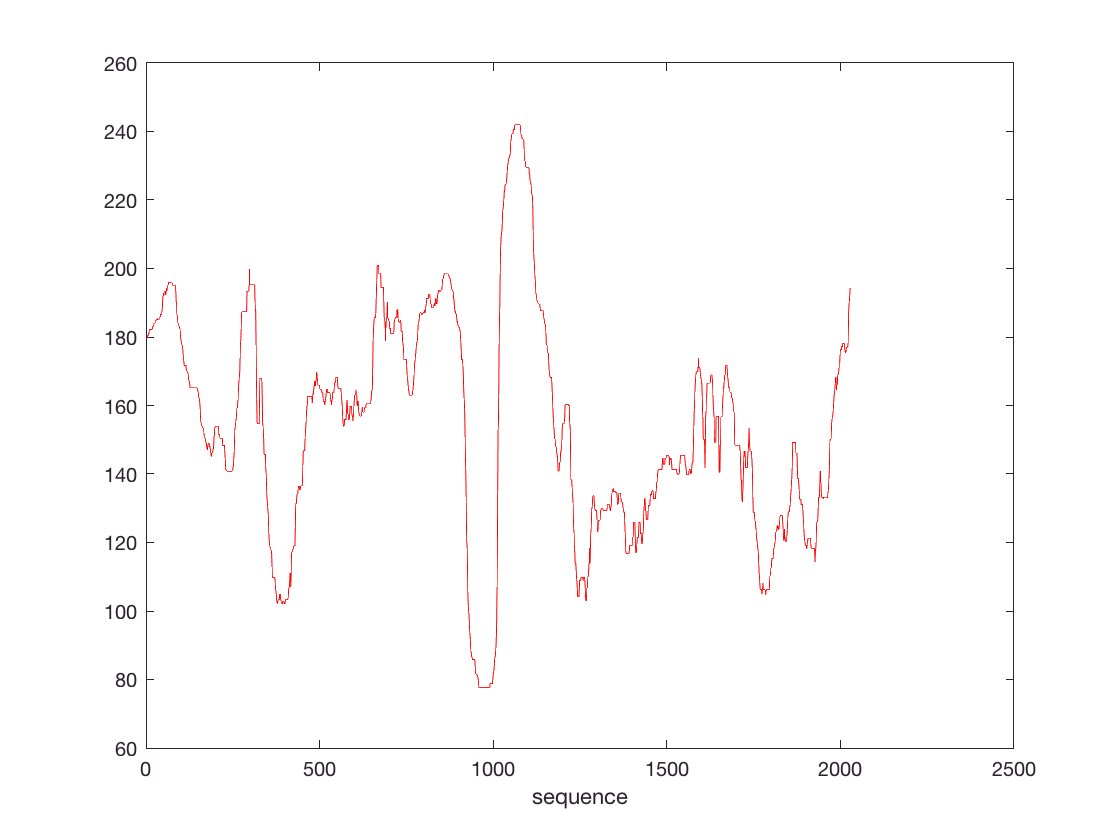

noempty_mag = csi_magnitude(csi_magnitude>=0);
len = length(noempty_mag);
group_size = 100;
smoothed_mag = zeros(1, len-group_size+1);
for i = 1:len-group_size+1
    smoothed_mag(i) = median(noempty_mag(i:i+group_size-1));
end
figure()
plot(smoothed_mag, 'r');
xlabel('sequence');
ylabel('');

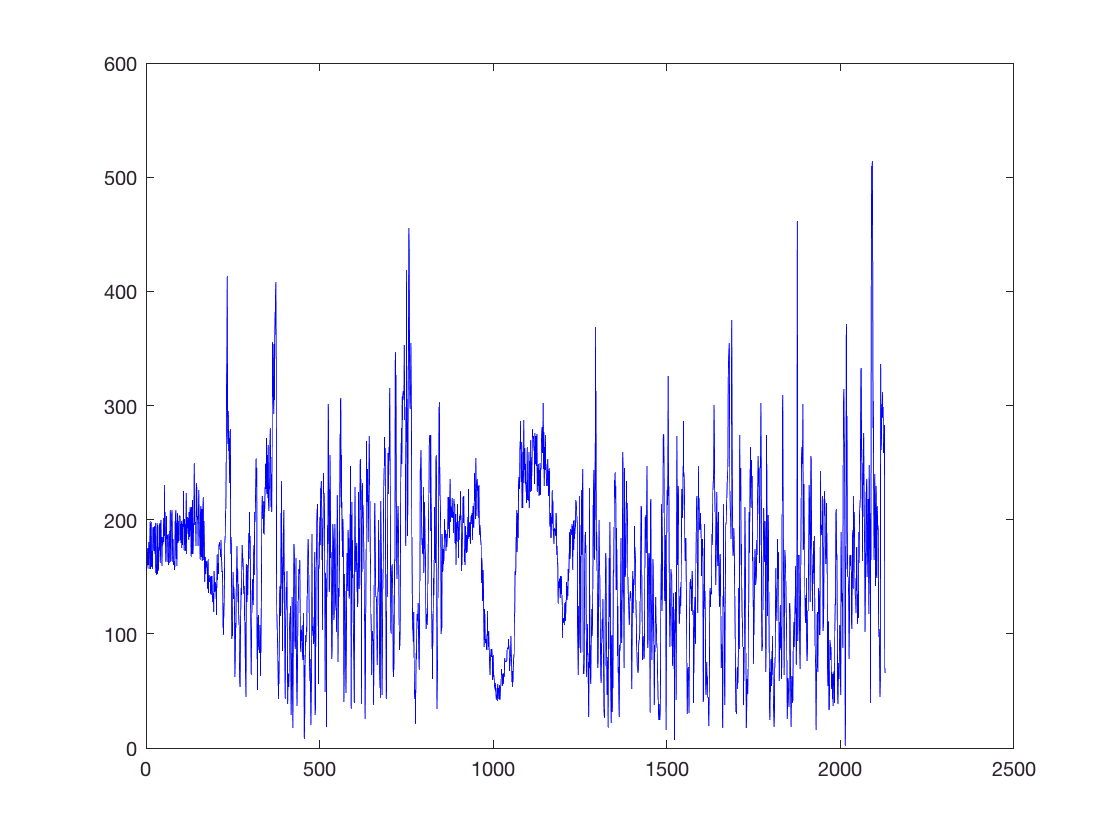

plot(noempty_mag, 'b')

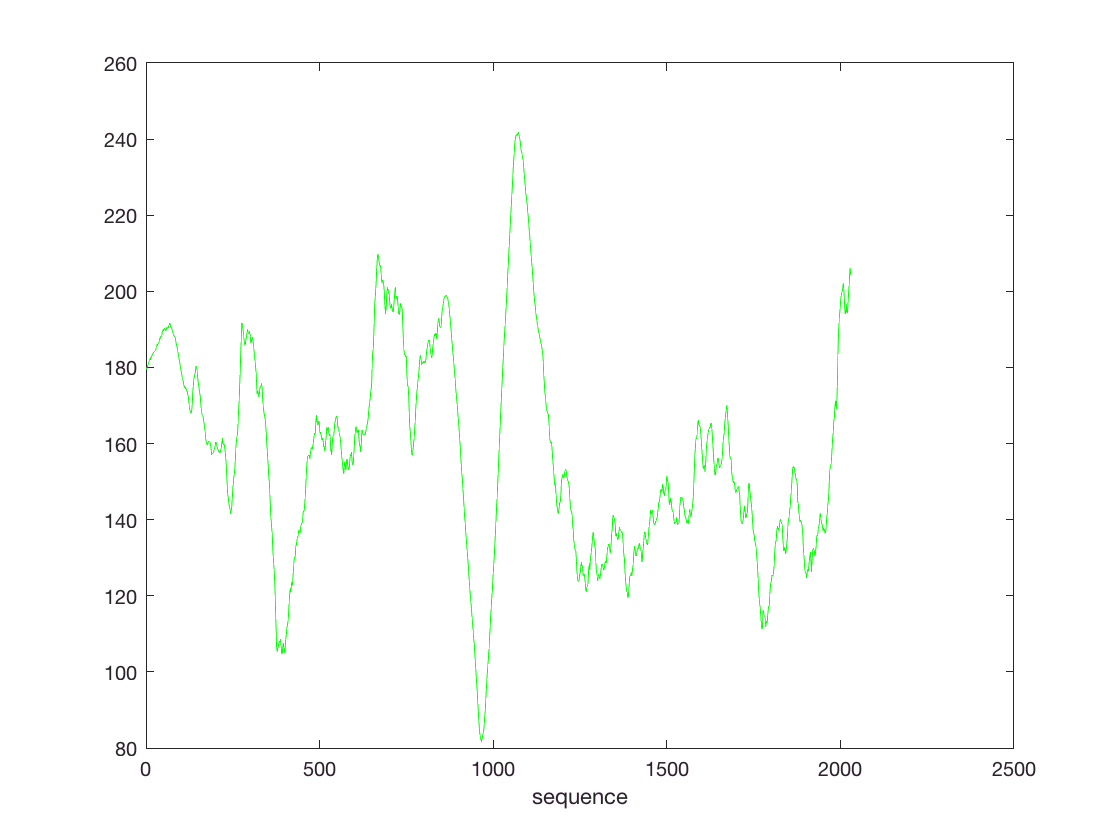

group_size = 100;
mean_mag = zeros(1, len-group_size+1);
for i = 1:len-group_size+1
    mean_mag(i) = mean(noempty_mag(i:i+group_size-1));
end
figure()
plot(mean_mag, 'g');
xlabel('sequence');
ylabel('');

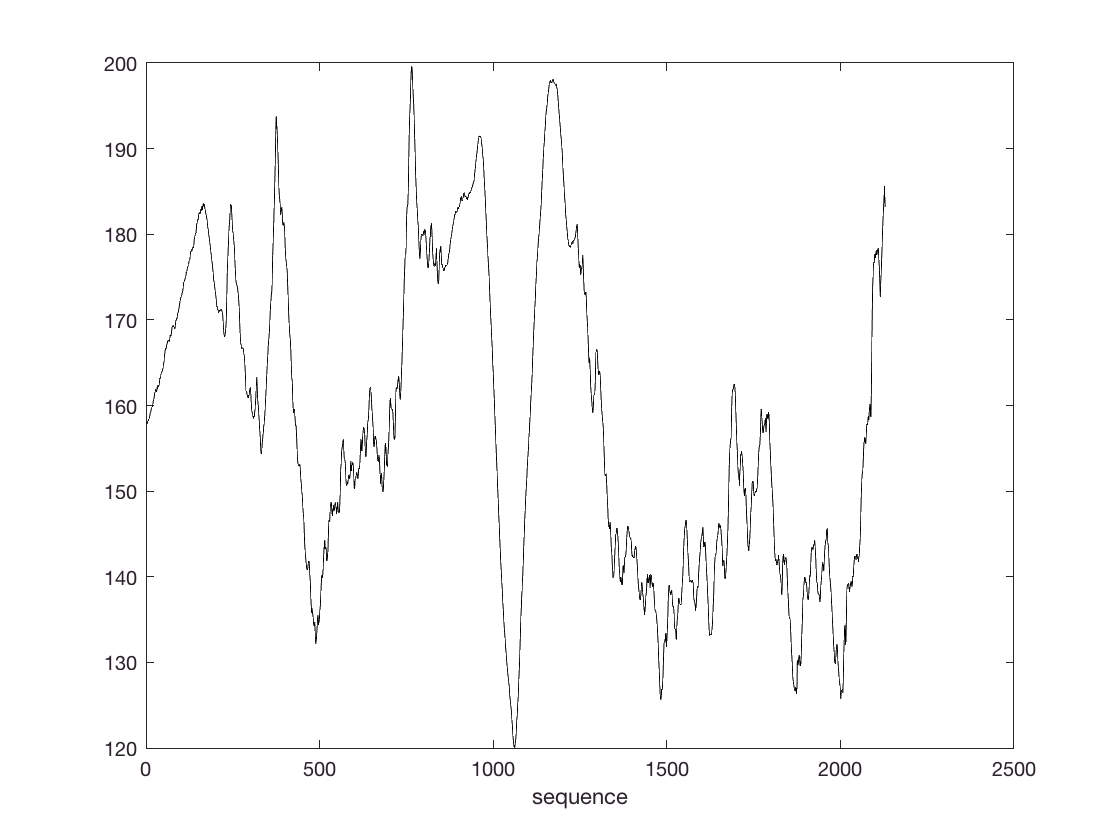

rotate = zeros(1, len);
rotate(1) = noempty_mag(1);
alpha = 0.01;
for i = 2:len
    rotate(i) = (1-alpha)*rotate(i-1)+alpha*noempty_mag(i);
end
figure()
plot(rotate, 'k');
xlabel('sequence');
ylabel('');